Let's run adaptive RK on  $u'=e^{t-u\sin u}$. 

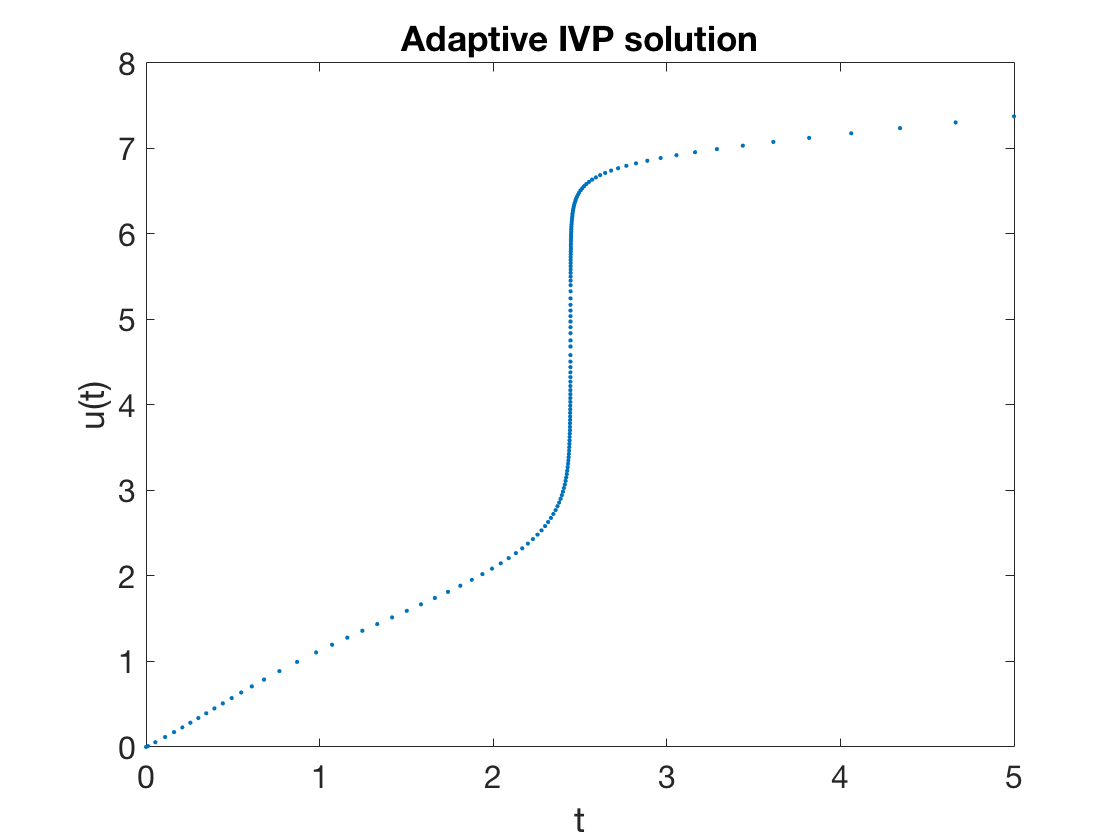

f = @(t,u) exp(t-u*sin(u));
[t,u] = rk23(f,[0,5],0,1e-5);
plot(t,u,'.')
xlabel('t'),  ylabel('u(t)')  % ignore this line
title('Adaptive IVP solution')  % ignore this line

The solution makes a very abrupt change near $t=2.4$. The resulting time steps vary over three orders of magnitude.

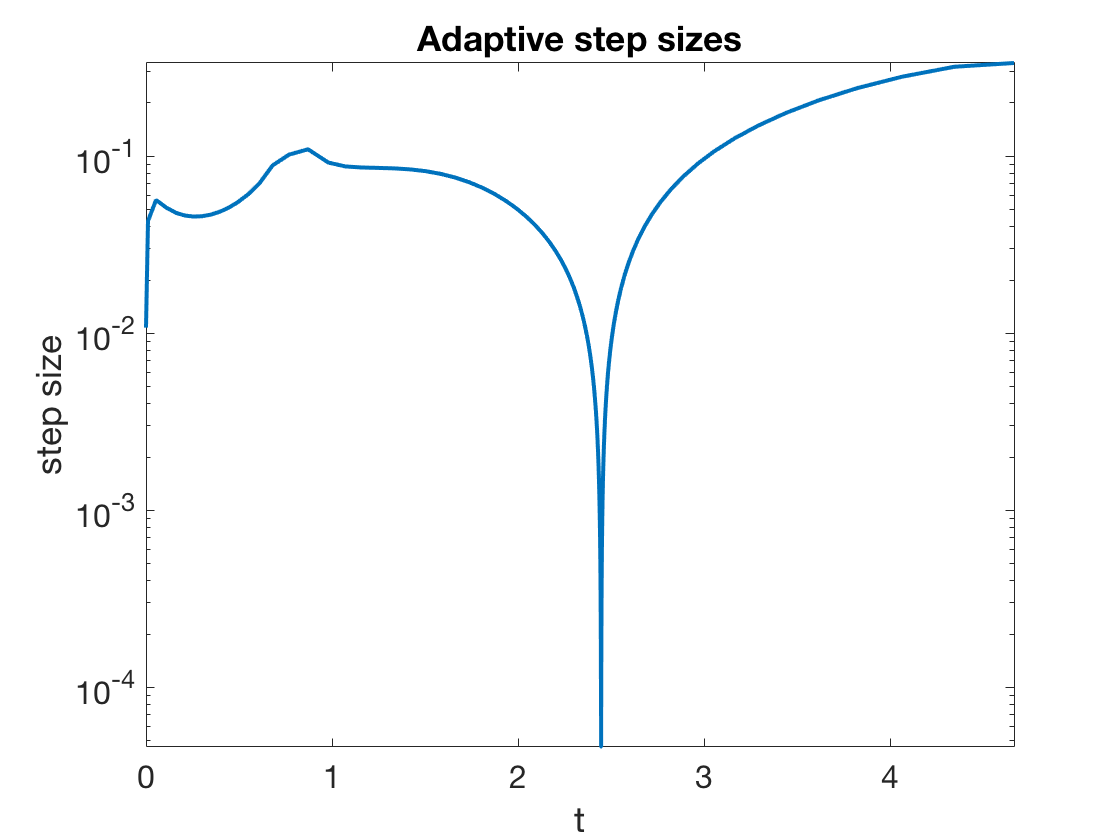

semilogy(t(1:end-1),diff(t))
axis tight, title('Adaptive step sizes')  % ignore this line  
xlabel('t'),  ylabel('step size')  % ignore this line

If we had to run with a uniform step size to get this accuracy, it would be

h_min = min(diff(t))

h_min =    4.6097e-05


On the other hand, the average step size that was actually taken was

h_avg = mean(diff(t))

h_avg =    3.2051e-02


We took fewer steps by a factor of almost 1000! Even accounting for the extra stage per step and the occasional rejected step, the savings are clear.